clear all;
close all;
addpath('./utils/matlab_code-SSD/');


% Parameters
N = 100;  % Number of points in the time series
num_predict = 1;
optimal_order = 4;  % Set a fixed optimal order for simplicity
L = floor((N-1) / 2);

% Generate sinusoidal signals with exponential decay
t = (1:N)';

rs = 0;
signal1 = 10 * sin(2 * pi * 0.1 * t) %.* exp(-0.01 * t);

signal1 =     5.8779
    9.5106
    9.5106
    5.8779
    0.0000
   -5.8779
   -9.5106
   -9.5106
   -5.8779
   -0.0000


signal2 = 10 * sin(2 * pi * 0.05 * t) %.* exp(-0.01 * t);

signal2 =     3.0902
    5.8779
    8.0902
    9.5106
   10.0000
    9.5106
    8.0902
    5.8779
    3.0902
    0.0000


signal3 = 10 * sin(2 * pi * 0.02 * t) %.* exp(-0.01 * t);

signal3 =     1.2533
    2.4869
    3.6812
    4.8175
    5.8779
    6.8455
    7.7051
    8.4433
    9.0483
    9.5106


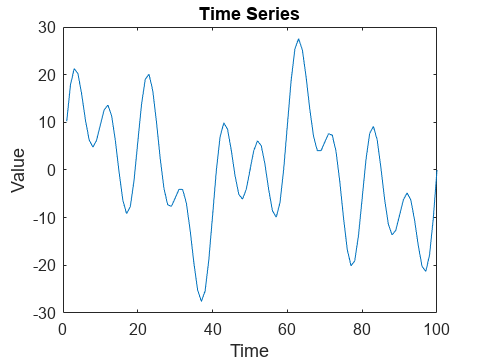


% Combine signals to form the time series
time_series = signal1 + signal2 + signal3;

% Ground truth for point 100
ground_truth = time_series(N);

% Plot the time series
figure;
plot(time_series);
title('Time Series');
xlabel('Time');
ylabel('Value');


% Prepare storage for predictions
predictions_full = zeros(1, 1);
predictions_components = zeros(1, 1);

% Full time series prediction using AR model
model_full = ar(time_series(1:end-1), optimal_order)  % AR(optimal_order) model

model_full =
Discrete-time AR model: A(z)y(t) = e(t)                        
  A(z) = 1 - 3.558 z^-1 + 5.118 z^-2 - 3.519 z^-3 + 0.9765 z^-4
                                                               
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=4
   Number of free coefficients: 4
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                           
Estimated using AR ('fb/now') on time domain data.
Fit to estimation data: 98.96%                    
FPE: 0.01781, MSE: 0.01642                        
 
Model Properties


pred_full = forecast(model_full, time_series(1:end-1), num_predict);
predictions_full(1) = pred_full(end);

% Decomposition using SSD
Fs = 1;  % Sampling frequency (you may need to adjust this based on your data)
th = 0.005;  % Threshold for stopping the decomposition
maxNumberofComponents = 3;  % Maximum number of components to extract

H2D = hankel(time_series(1:L),time_series(L:end-1));

SSDcomponents = SSD(H2D, Fs, th, maxNumberofComponents);

% Prepare for component-based prediction
num_components = size(SSDcomponents, 1);
pred_components = zeros(num_components, 1);

figure;
plot(time_series, 'k', 'DisplayName', 'Original');
hold on;

for comp = 1:num_components
    % Extract the component
    component_series = SSDcomponents(comp, :);

    % Plot the component
    plot(component_series, 'DisplayName', ['Component ', num2str(comp)]);

    % Fit AR model to the component and forecast
    model_comp = ar(component_series', optimal_order)
    pred_comp = forecast(model_comp, component_series', num_predict);
    pred_components(comp) = pred_comp(end);
end

model_comp =
Discrete-time AR model: A(z)y(t) = e(t)                        
  A(z) = 1 - 3.357 z^-1 + 4.738 z^-2 - 3.251 z^-3 + 0.9344 z^-4
                                                               
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=4
   Number of free coefficients: 4
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                           
Estimated using AR ('fb/now') on time domain data.
Fit to estimation data: 98.04%                    
FPE: 0.03195, MSE: 0.03185                        
 
Model Properties

model_comp =
Discrete-time AR model: A(z)y(t) = e(t)                       
  A

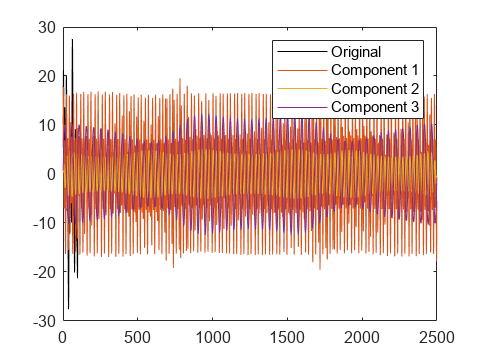


hold off;
legend show;


% Sum the predictions of the components
predictions_components(1) = sum(pred_components);

% Display the predictions
disp('Predictions from Full Time Series:');

Predictions from Full Time Series:


disp(predictions_full);

   -0.0467




disp('Predictions from Component Decomposition (SSD):');

Predictions from Component Decomposition (SSD):


disp(predictions_components);

    6.7246




% Compare predictions with ground truth
disp(['Ground truth: ', num2str(ground_truth)]);

Ground truth: -2.3874e-14


disp(['Error (Full Time Series): ', num2str(abs(predictions_full - ground_truth))]);

Error (Full Time Series): 0.046655


disp(['Error (Component Decomposition): ', num2str(abs(predictions_components - ground_truth))]);

Error (Component Decomposition): 6.7246
